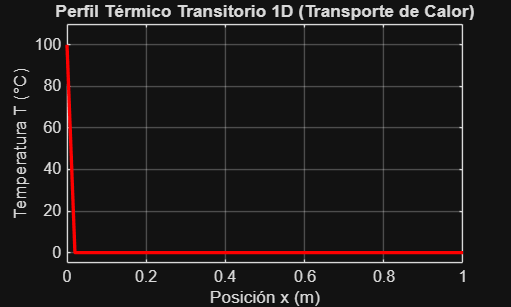

%% MODELADO NUMÉRICO TRANSITORIO DEL TRANSPORTE DE CALOR 1D
% Basado estrictamente en el paper: MN_P2_Grupo_4.pdf
clear; clc; close all;

%% 1. PARÁMETROS DEL PROBLEMA Y MESH
L = 1.0;                 % Longitud del tubo (m)
N = 51;                  % Número de nodos espaciales
dx = L / (N - 1);
x = linspace(0, L, N)';

v = 0.5;                 % Velocidad constante del fluido (m/s)
alpha0 = 0.01;           % Difusividad térmica base (m^2/s)
beta = 0.2;              % Coeficiente de variación no lineal
T0 = 0.0;                % Temperatura de referencia (°C)

T_final = 2.0;           % Tiempo total
h = 0.01;                % Paso de tiempo dt
num_pasos = round(T_final / h);

% Parámetro gamma para SDIRK4 (Ecuación 8)
gamma = 1/4;

%% 2. CONDICIONES INICIALES Y DE FRONTERA
T = zeros(N, 1);
T(1) = 100.0;            % Borde izquierdo caliente (Dirichlet)
T(N) = 0.0;              % Borde derecho frío (Dirichlet)

figure('Name', 'Evolución Perfil Térmico 1D');
plot(x, T, 'r-', 'LineWidth', 2);
title('Perfil Térmico Transitorio 1D (Transporte de Calor)');
xlabel('Posición x (m)'); ylabel('Temperatura T (°C)');
grid on; ylim([-5, 110]);

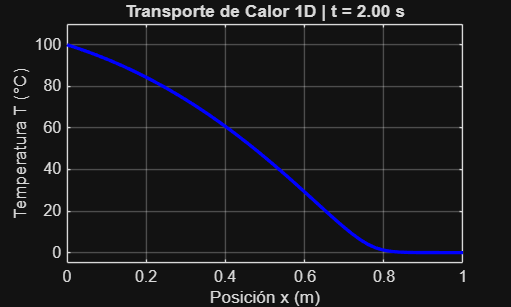


%% 3. BUCLE TEMPORAL (INTEGRACIÓN TRANSITORIA)
tic;
for n = 1:num_pasos
    T_old = T;
    
    % Etapa SDIRK4 / Newton-Raphson / Gauss-Seidel
    [f_old, ~] = evaluar_f(T_old, v, alpha0, beta, T0, dx, N);
    r1 = T_old;
    
    % Resolver etapa no lineal implícita con Newton-Raphson
    U1 = newton_raphson_sdirk(T_old, r1, h, gamma, v, alpha0, beta, T0, dx, N, 1e-6);
    
    T = U1; % Actualización del tiempo n+1
    T(1) = 100.0; T(N) = 0.0; % Re-aplicar bordes
    
    % Graficación periódica
    if mod(n, 10) == 0
        plot(x, T, 'b-', 'LineWidth', 2);
        title(sprintf('Transporte de Calor 1D | t = %.2f s', n*h));
        xlabel('Posición x (m)'); ylabel('Temperatura T (°C)');
        grid on; ylim([-5, 110]);
        drawnow;
    end
end

tiempo_cpu = toc;

fprintf('\nSimulación 1D finalizada con éxito en %.4f segundos.\n', tiempo_cpu);


Simulación 1D finalizada con éxito en 3.3938 segundos.
